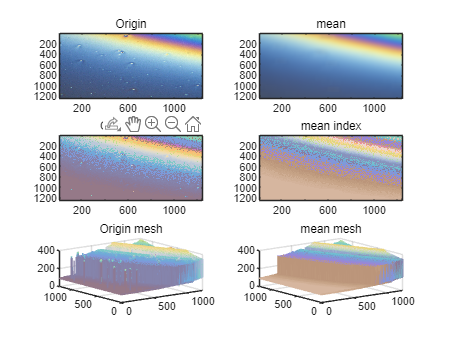

clc
clear
N = 100;%卷积核大小
I = imread('1.jpg');
subplot(3,2,1)
image(I)
title('Origin')
load('rm_f.mat');
rgb = transpose(rgbmatrix(:,1:400))/256;
rgb(rgb>1) = 1;
customCMap = uint8(rgbmatrix(:,1:400)');
colormap(customCMap);
X = rgb2ind(I,rgb);
subplot(3,2,3)
imagesc(X)
title('Origin index')
I = double(I);
kernel = ones(N, N) / N^2;
test = imfilter(I, kernel, 'symmetric');
test = uint8(test);
subplot(3,2,2)
image(test);
title('mean')
X_I = rgb2ind(test,rgb);
subplot(3,2,4)
imagesc(X_I)
title('mean index')
subplot(3,2,5)
mesh(imrotate(X,-90))
title('Origin mesh')
subplot(3,2,6)
mesh(imrotate(X_I,-90))
title('mean mesh')